% 2025 Balance Calculator
% v1
clearvars; clc

close all

sfSplit = true; % is SF-1 split?
saveBC = false;
resultsFP = "C:\Users\EastonPrice\OneDrive - Spire Motorsports LLC\Documents\2025(P) Race Engineering\Balance Calculator\2025\Veg\24VEG_wThrottlePlate_2025BCBatch_LTS_FilteredResults.csv";
summaryFP = "C:\Users\EastonPrice\OneDrive - Spire Motorsports LLC\Documents\2025(P) Race Engineering\Balance Calculator\2025\Veg\24VEG_wThrottlePlate_2025BCBatch_LTS_Summary.csv";


resultsRaw = readmatrix(resultsFP, "Range", "A1", 'OutputType','char');
summaryRaw = readmatrix(summaryFP, "Range", "A1", 'OutputType','char');

% gets paramater headers/names from summary file using the notes index
paramHeaders = getParamHeaders(summaryRaw);

% gets both parameter and output data, based on index of laptime.
% sfSplit should have value of true if the SF is split into a and b
% sectionssave
[paramData, outputs, lapTime] = getDataOfInterest(resultsRaw,paramHeaders, sfSplit);



idxIsNum = cellfun(@isnumeric, lapTime);
lapTime_num = convertCellChars2Num(lapTime);
idxEmpty = cellfun(@isempty, lapTime_num);
lapTime_num(idxEmpty) = num2cell(NaN);
lapTime_num = cell2mat(lapTime_num);
idx0LapTime = (lapTime_num == 0);
rowsWithTrue = find(any(idx0LapTime, 2));



outputNames = outputs(1,:); % output names + segments, first row of outputs
idxUnderScore = strfind(outputNames(1,:), '_'); % Assuming output names occur before the first underscore

for k = 1:length(idxUnderScore)
    sectorNames{k} = outputNames{k}(idxUnderScore{k}(1)+1:end); % extracted segment name
    outputNames{k} = outputNames{k}(1:idxUnderScore{k}(1)-1); % extracted output name

end

outputNames = unique(outputNames);
sectorNames = unique(sectorNames);

idxUnhooked = find(contains(paramData(1,:), 'Unhooked'));
idxToeInches = find(contains(paramData(1,:), 'Toe Inches'));
idxfARB = find(contains(paramData(1,:), 'ARB Front'));
idxrARB = find(contains(paramData(1,:), 'ARB Rear'));


paramData(:, [idxUnhooked, idxToeInches, idxfARB, idxrARB]) = [];

## Find Parameter Indexes

baselineParam = paramData(2,:);

paramDeltasIdx = getParamIndexes(summaryRaw);



## Get outputs of interest

outputsOI = getCalcData(outputs, lapTime);

idxEmpty = find(cellfun(@isempty, outputsOI));


clear linFit currInputIdx
minRlinear = 0.85;
minRquad = 0.7;

q = 1;

linFit(2:size(paramData,2)+1,1) = paramData(1,:);
linFit(1,2:size(outputsOI,2)+1) = outputsOI(1,:);

quadFit = linFit;
quadFit{1,1} = "a";
quadFit{size(paramData,2) + 2, 1} = "b";
boffset = size(paramData,2) + 1;
quadFit{boffset + size(paramData,2) + 2,1} = "c";
coffset = boffset + size(paramData,2) + 1;

quadFit{coffset + size(paramData,2) + 2,1} = "Baseline Data";
baseOffset = coffset + size(paramData,2) + 2 + 1;

quadFit(boffset + 2:boffset+2+size(paramData,2)-1,1) = paramData(1,:);
quadFit(coffset + 2: coffset+2+size(paramData,2)-1,1) = paramData(1,:);

linFit{end+1,1} = "Baseline Setup";
[nr, ~] = size(linFit);
for k = 1:size(paramData,2)
    currB = paramData{2,k};
    currB = replace(currB, 'P', '');
    currB = str2num(currB);
    linFit{nr,k+1} = paramData{1,k};
    linFit{nr+1,k+1} = currB;
end

r = 2; c = 2;
for i = 1:size(paramData,2)
    currInputIdx = find(contains(paramDeltasIdx(1,:), paramData{1,i}));
    currInputDeltaIdx = paramDeltasIdx{2,currInputIdx};

    currInputs = paramData(currInputDeltaIdx, i);

    if contains(paramData(1,i), 'Blade')
        for q = 1:numel(currInputs)
            currInputs{q} = replace(currInputs{q}, 'P', '');
        end
    end

    currInputs = convertCellChars2Num(currInputs);
    rawInputs = currInputs;



    for o = 1:size(outputsOI,2)

        currOutputs = outputsOI(currInputDeltaIdx, o);

        currOutputs = convertCellChars2Num(currOutputs);
        idxIsEmpty = find(cellfun(@isempty, currOutputs));
        currOutputs(idxIsEmpty) = {0};

        idxIs0LapTime = ismember(currInputDeltaIdx, rowsWithTrue);
        if any(idxIs0LapTime)
            currInputs = currInputs(~idxIs0LapTime);
            currOutputs = currOutputs(~idxIs0LapTime);
        end

        xraw = cell2mat(currInputs);
        yraw = cell2mat(currOutputs);

        [y, io] = rmoutliers(yraw, 'movmedian',3);
        x = xraw;
        x(io) = [];

        if nnz(io) ~= 0
            removedOutliers{q,1} = paramDeltasIdx{1,currInputIdx};
            removedOutliers{q,2} = outputsOI{1,o};
            q = q + 1;
        end


        [pl, sl] = polyfit(x, y, 1);
        [pq, sq] = polyfit(x, y, 2);

        quadFit{baseOffset, c} = cell2mat(convertCellChars2Num(outputsOI(2,o)));

        

        if sl.rsquared > sq.rsquared
            linFit{r,c} = pl(1);
            quadFit{r,c} = 12345;

        else
            linFit{r,c} = 12345;
            quadFit{r,c} = pq(1);
            quadFit{r + boffset, c} = pq(2);
            quadFit{r + coffset, c} = pq(3);
        end

        if contains(paramData(1,i), 'LTS Track Mu') && contains(outputsOI(1, o), 'Times')
            linFit{r,c} = pl(1);
            quadFit{r,c} = 12345;
        end


        c = c + 1;

        currInputs = rawInputs;
    end

    c = 2;
    r = r + 1;
end
open linFit 
open quadFit


## Parameter Plots

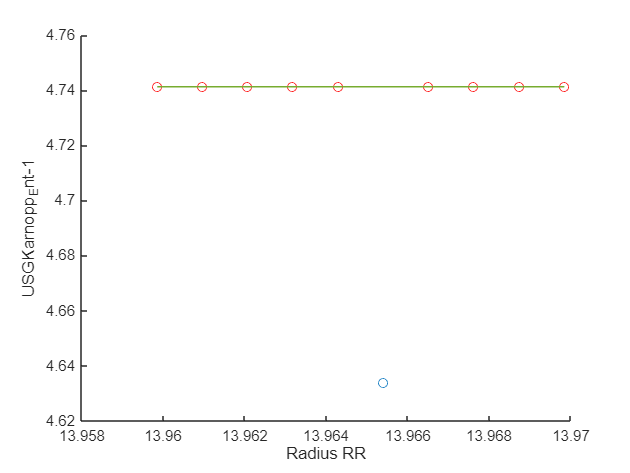



getVariable = 'Radius RR'     ;
getOutput = 'USGKarnopp_Ent-1';



currInputIdx = find(contains(paramDeltasIdx(1,:), getVariable));
currInputDeltaIdx = paramDeltasIdx{2,currInputIdx};

currInputs = paramData(currInputDeltaIdx, contains(paramData(1,:), getVariable));


currOutputs = outputsOI(currInputDeltaIdx, contains(outputsOI(1,:), getOutput));

currOutputs = convertCellChars2Num(currOutputs);
idxIsEmpty = find(cellfun(@isempty, currOutputs));
currOutputs(idxIsEmpty) = {0};



idxIs0LapTime = ismember(currInputDeltaIdx, rowsWithTrue);
if any(idxIs0LapTime)
    currInputs = currInputs(~idxIs0LapTime);
    currOutputs = currOutputs(~idxIs0LapTime);
end


x = cell2mat(convertCellChars2Num(currInputs));
y = cell2mat(currOutputs);

scatter(x,y);
xlabel(getVariable);
ylabel(getOutput)

[y, io] = rmoutliers(y, 'movmedian',3);
x(io) = [];
hold on
scatter(x,y, 'r')
hold off

[p1, s1] = polyfit(x,y,1);
[p2, s2] = polyfit(x,y,2);

syms d
hold on
if s1.rsquared > s2.rsquared
    fplot(p1(1)*d + p1(2), [min(x) max(x)])
    % title('lin')
else
    fplot(p2(1)*d^2 + p2(2)*d + p2(3), [min(x) max(x)])
    % title('quad')
end

hold off
hold on
fplot(p1(1)*d + p1(2), [min(x) max(x)]);
hold off

[p3, s3] = polyfit(x,y,3);
hold on
fplot(p3(1)*d^3 + p3(2)*d^2 + p3(3)*d + p3(4), [min(x) max(x)])
hold off

## Variation Plots

varChannel = [paramData, outputsOI];

for c = 1:size(varChannel, 2)
    for r = 2:size(varChannel,1)
        if ischar(varChannel{r,c})
            varChannel{r,c} = replace(varChannel{r,c}, 'P', '');
            varChannel{r,c} = str2num(varChannel{r,c});
        end

        
    end
    varChannel{1,c} = convertCharsToStrings(varChannel{1,c});
end



## Save and Export


if saveBC
    templateFP = "C:\Users\EastonPrice\Documents\2025(P) Race Engineering\Balance Calculator\2025\2025BalanceCalculator_Template.xlsm";

    pasteFP = "C:\Users\EastonPrice\Documents\2025(P) Race Engineering\Balance Calculator\2025\Paste_BC.xlsx.xlsm";

    copyWorkbook(templateFP, pasteFP);

    params = linFit(2:end-2,1);
    outputs_NamePaste = linFit(1,2:end);

    linData = linFit(2:end,:);

    quadData = quadFit(2:end,:);

    writecell(outputs_NamePaste, pasteFP, 'Sheet', 'Import Quad', 'Range', 'A1');

    writecell(quadData, pasteFP, 'Sheet', 'Import Quad', 'Range', 'A3');

    writecell(outputs_NamePaste, pasteFP, 'Sheet', 'Maths', 'Range', 'B1');

    writecell(linData, pasteFP, 'Sheet', 'Maths', 'Range', 'X1');

    writecell(aeroPlotData, pasteFP, 'Sheet', 'Aero Plotter Maths', 'Range', 'K1');

    fprintf('Data pasted to %s', pasteFP);


## Copy Template File and Paste into Normal Folder



    % Split Full File Path
    sp = split(fp,'\');
    destFolder = join(sp(1:end-1),'\'); % Destination Folder

    raceID = char(sp(end-1));
    idx = false(size(raceID));
    idxUnd = strfind(raceID,'_');
    for k = idxUnd + 1:length(raceID)
        curr = str2num(raceID(k));
        if isempty(curr)
            idx(k) = 1;
        else
            idx(k) = 0;
        end
    end
    idx = logical(idx);
    newFN = strcat(raceID(1:2),'_',raceID(idx),raceID(end),'_77_Balance Calculator.xlsm');

    destFile = strcat(destFolder,'\',newFN)

    copyWorkbook(pasteFP, destFile);

end